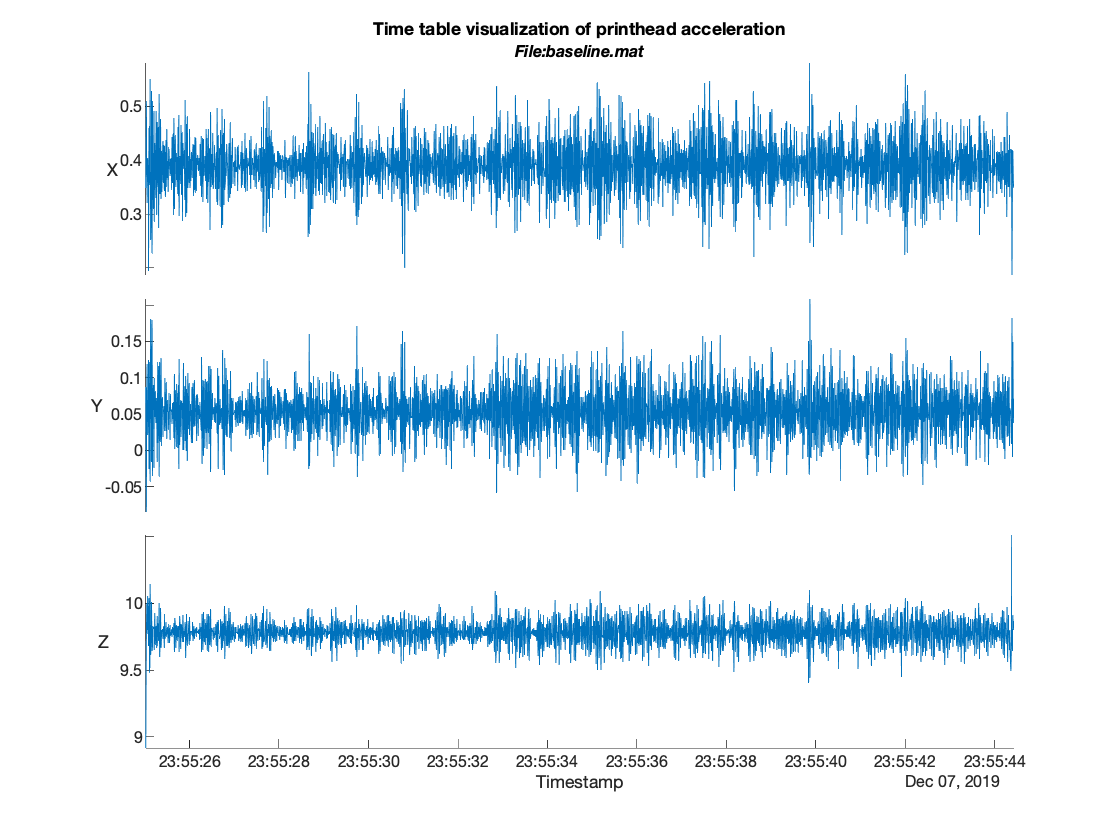

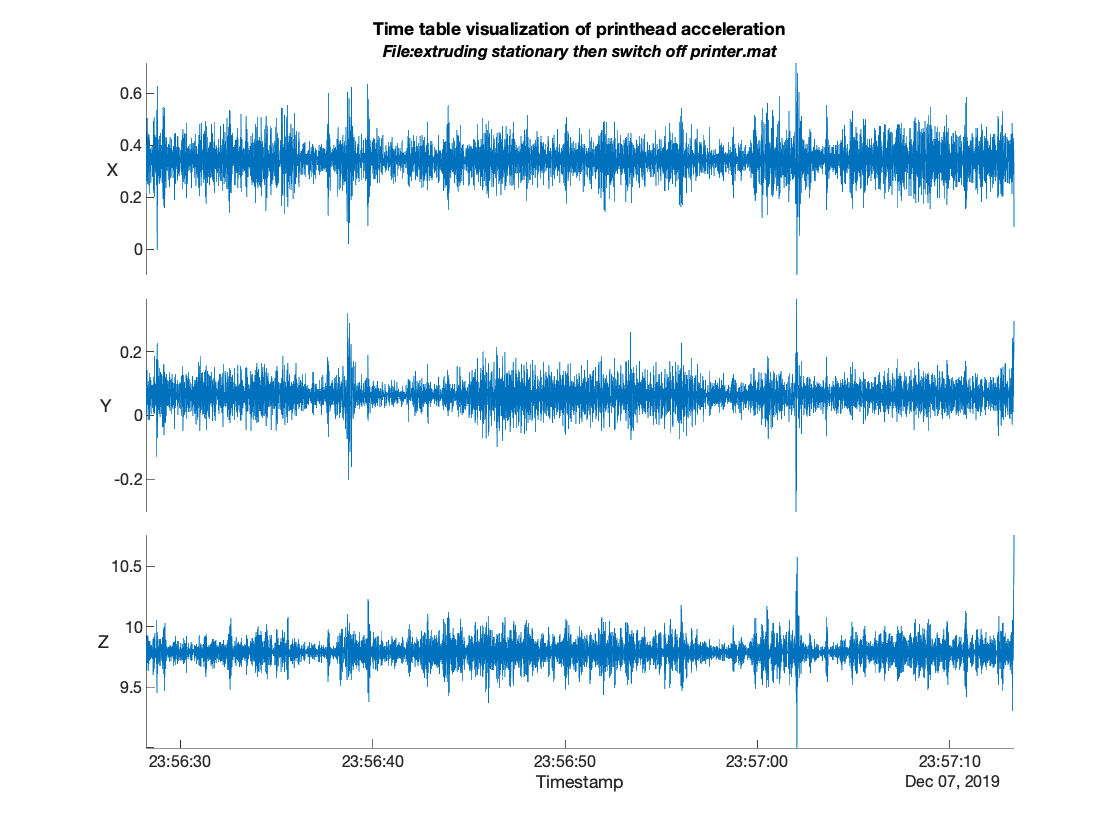

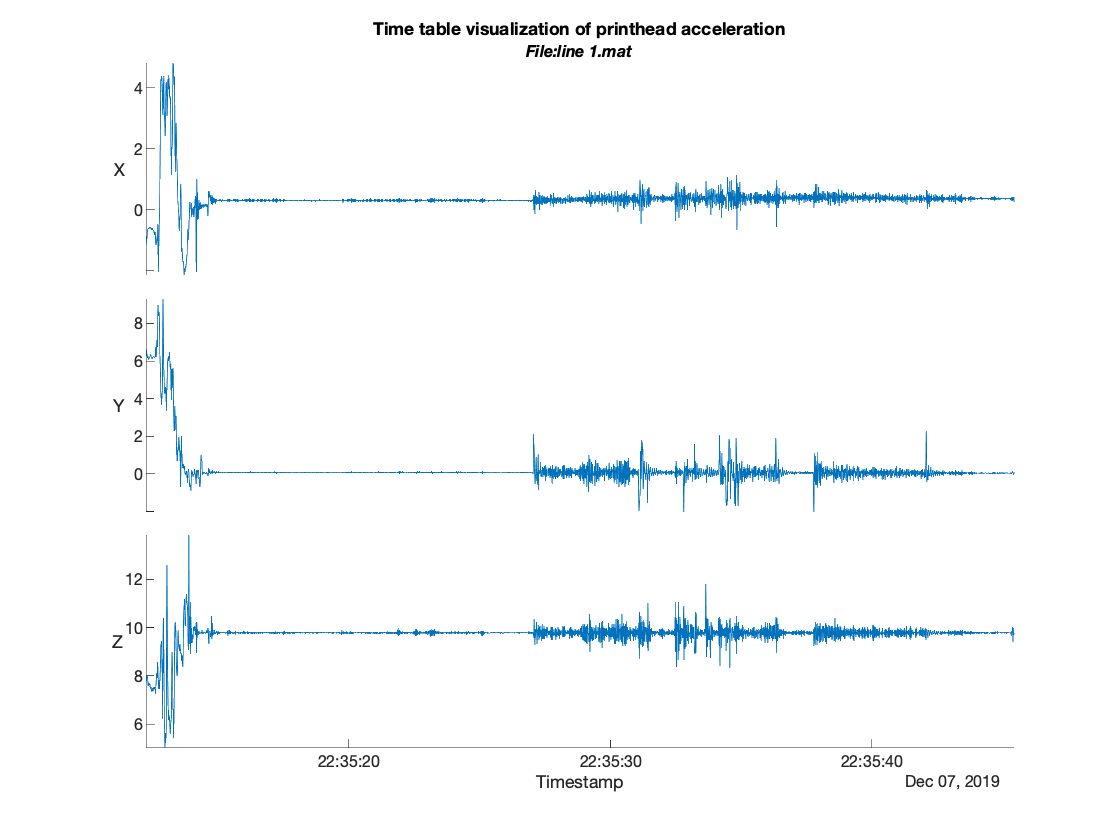

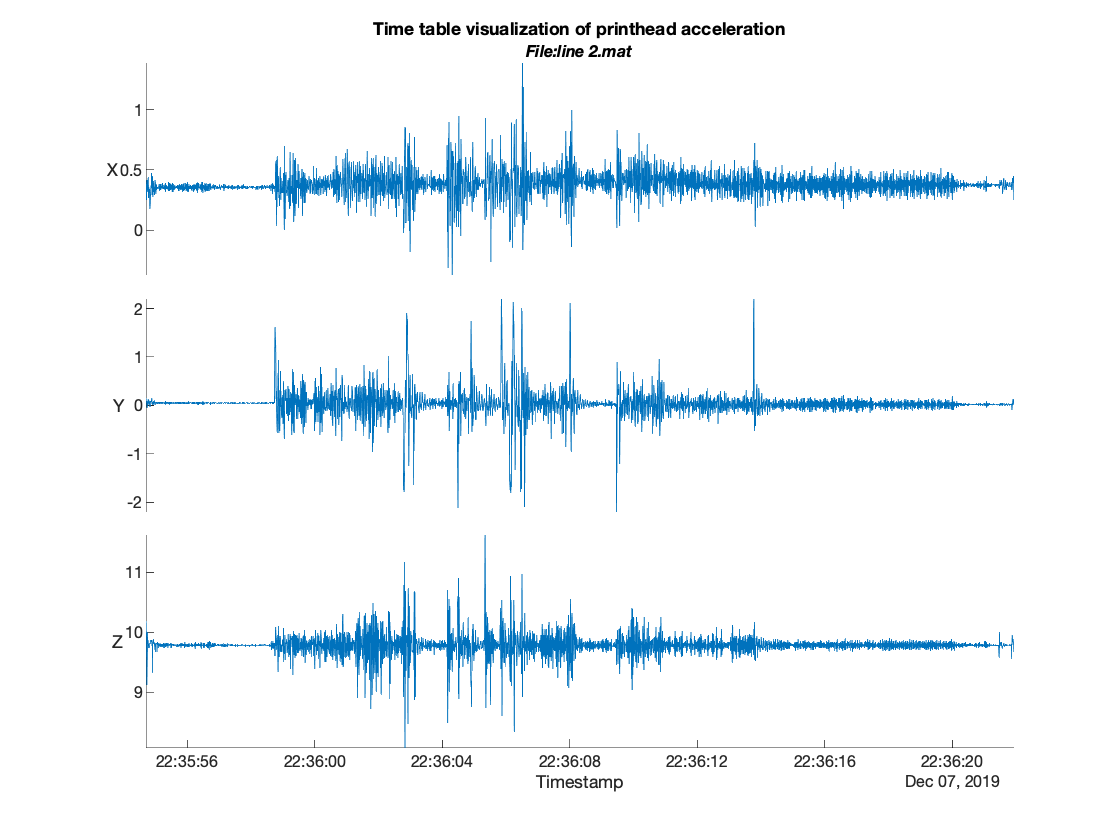

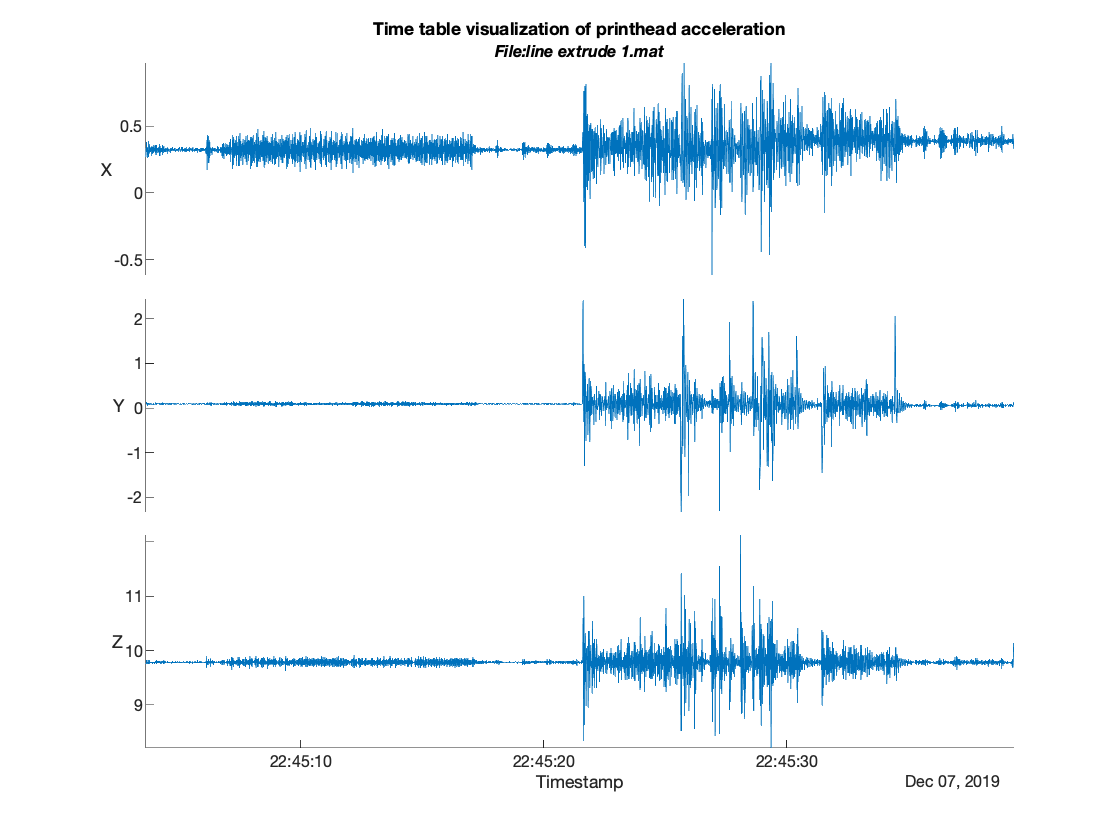

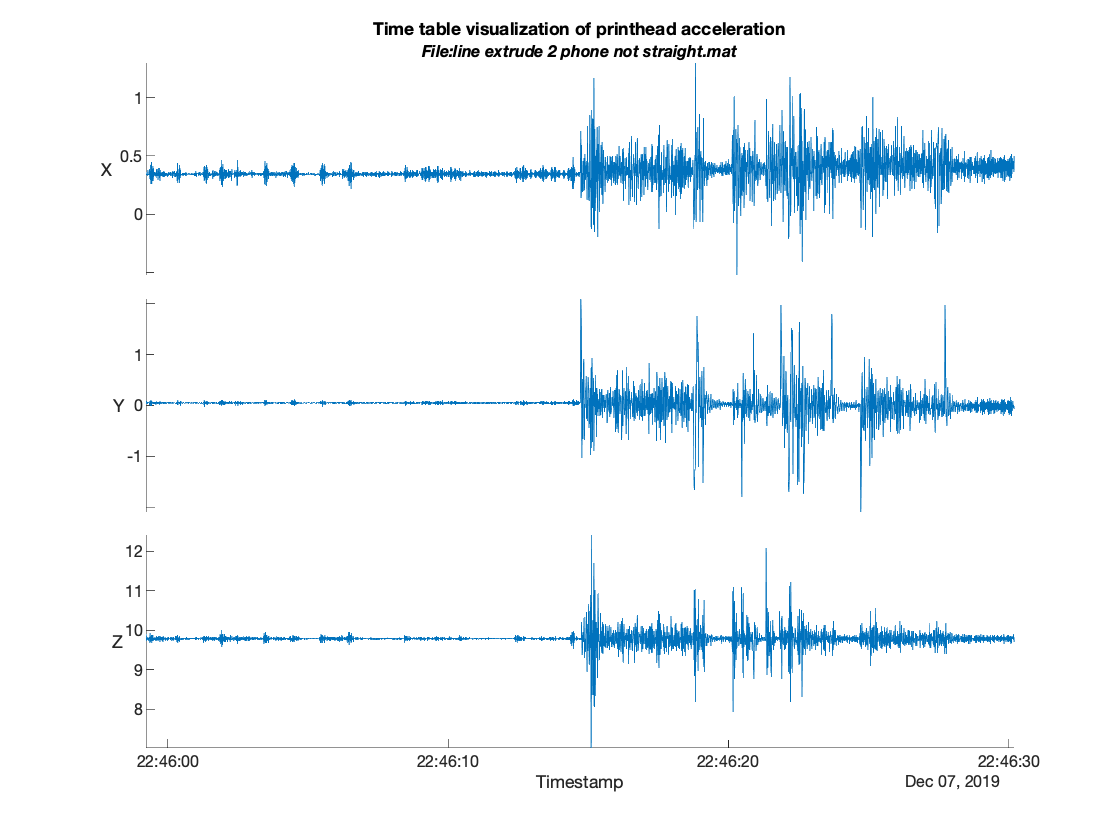

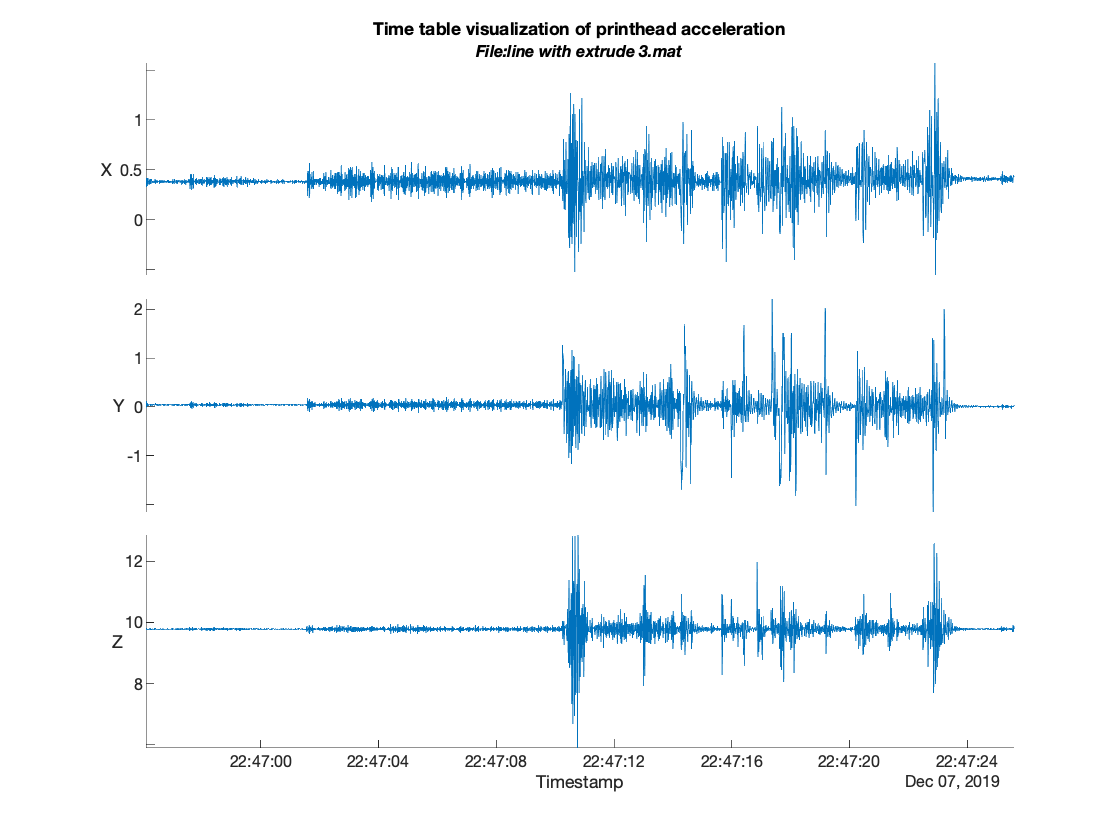

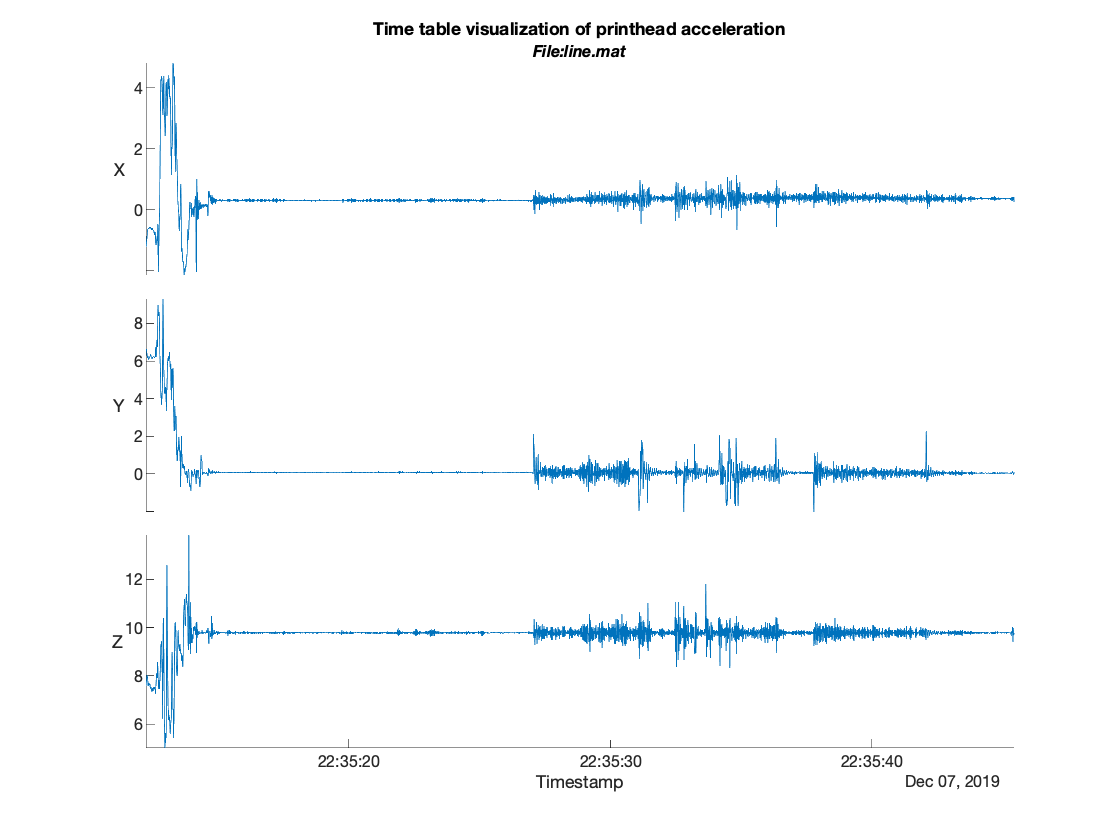

clear;

datasets = dir('data/*.mat');
numfiles = length(datasets);
% numfiles = 2
mydata = cell(1, numfiles);

% Import Data
for k = 1:numfiles
  mydata{k} = importdata(strcat('data/',datasets(k).name));
  mydata{k}.Source = datasets(k).name;
end

% Run simple analysis on all
for k = 1:length(mydata)
    sample = mydata(k);
    Acceleration = sample{1}.Acceleration;
    figure()
    stackedplot(Acceleration);
    title({'Time table visualization of printhead acceleration';strcat('\fontsize{8}\itFile:  ',sample{1}.Source)})
end